clear;
clc;

% Punto 1
% Se crean las variables 
m_log_y = 2;
var_log_y = 1.5;

syms My
syms var_y

% Media lognormal
M = exp(My-((var_y))/2)

$$M = {\mathrm{e}}^{\mathrm{My}-\frac{{\mathrm{var}}_{y}}{2}}$$


% Varianza lognormal
V = exp(2*My + var_y)*(exp(var_y)-1)

$$V = {\mathrm{e}}^{2\,\mathrm{My}+{\mathrm{var}}_{y}}\,\left({\mathrm{e}}^{{\mathrm{var}}_{y}}-1\right)$$


% se soluciona el sistema de ecuaciones
eqns = [M==m_log_y,V==var_log_y];
Sa = vpasolve(eqns,[My var_y])

Sa = struct with fields:
       My: 0.80182741081421941292416801264721
    var_y: 0.21736046050854820701387178237807


% Punto 2
% Se crean las variables de media y distribución estándar
mu = 10;
sigma = sqrt(200);

% Se calcula la distribución de probabilidad lognormal con los parámetros
% establecidos
pd = makedist('Lognormal','mu',10,'sigma',sqrt(200))

pd =   LognormalDistribution

  Lognormal distribution
       mu =      10
    sigma = 14.1421



% P[X>30]
p = logncdf(30,mu, sigma)

p = 0.3204

P_2 = 1-p

P_2 = 0.6796

% Punto 3

% Se cargan las distribuciones de conductividad para cada tipo de textura
% en el acuífero
K = load('K.m');
sand = K(1,:);
clay = K(2,:);
turb = K(3,:);

% Probabilidad para cada tipo de textura:
Ps = 0.7;
Pc = 0.2;
Pt = 0.1;

% Se calcula la distribución de condutividad para todo el acuífero de la
% siguiente forma:
P_total = Ps*sand + Pc*clay + Pt*turb

P_total =     0.0700    0.1100    0.0700    0.1100    0.2900    0.2100    0.0700    0.0700


% Punto 4
z1_m = 10;
z2_m = 25;
z1_v = 300;
z2_v = 400;
z1_std = sqrt(z1_v)

z1_std = 17.3205

z2_std = sqrt(z2_v)

z2_std = 20

p = 0.7;

% Covarianza
Cov_Z = p*z1_std*z2_std

Cov_Z = 242.4871


% Valor esperado
E_Y = z1_m + z2_m

E_Y = 35


% Varianza 
Var_Y = z1_v + z2_v + 2*Cov_Z

Var_Y = 1.1850e+03

% Punto 5

% Vectores de medias y varianzas de Z1 y Z2
mu = [z1_m z2_m]

mu =     10    25


sigma = [z1_v Cov_Z; Cov_Z z2_v]

sigma =   300.0000  242.4871
  242.4871  400.0000


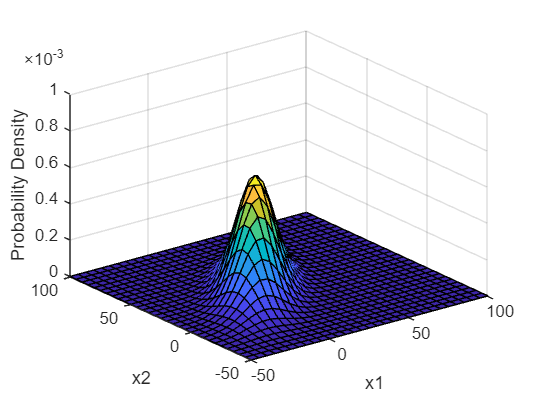


% Se crean los los valores en los cuales se calculará la probabilidad
x1 = -100:5:100;
x2 = -100:5:100;
[X1,X2] = meshgrid(x1,x2);
X = [X1(:) X2(:)];

% 
y = mvnpdf(X,mu,sigma);
y = reshape(y,length(x2),length(x1));



surf(x1,x2,y)
axis([-50 100 -50 100 0 0.001])
xlabel('x1')
ylabel('x2')
zlabel('Probability Density')


% P[Z1 < 30]
lim_inf = [-Inf -Inf];
lim_sup = [30 Inf];


% Calcular la probabilidad P(Z1 < 30)
% probabilidad = mvncdf(lim_sup, lim_inf, mu, sigma, [1 p; p 1]);